# Introduction to Matlab

Welcome to this introductory course on Matlab! This course is intended to help you start programming in Matlab from little or no prior experience. There are video tutorials for each exercise if you have questions along the way. 

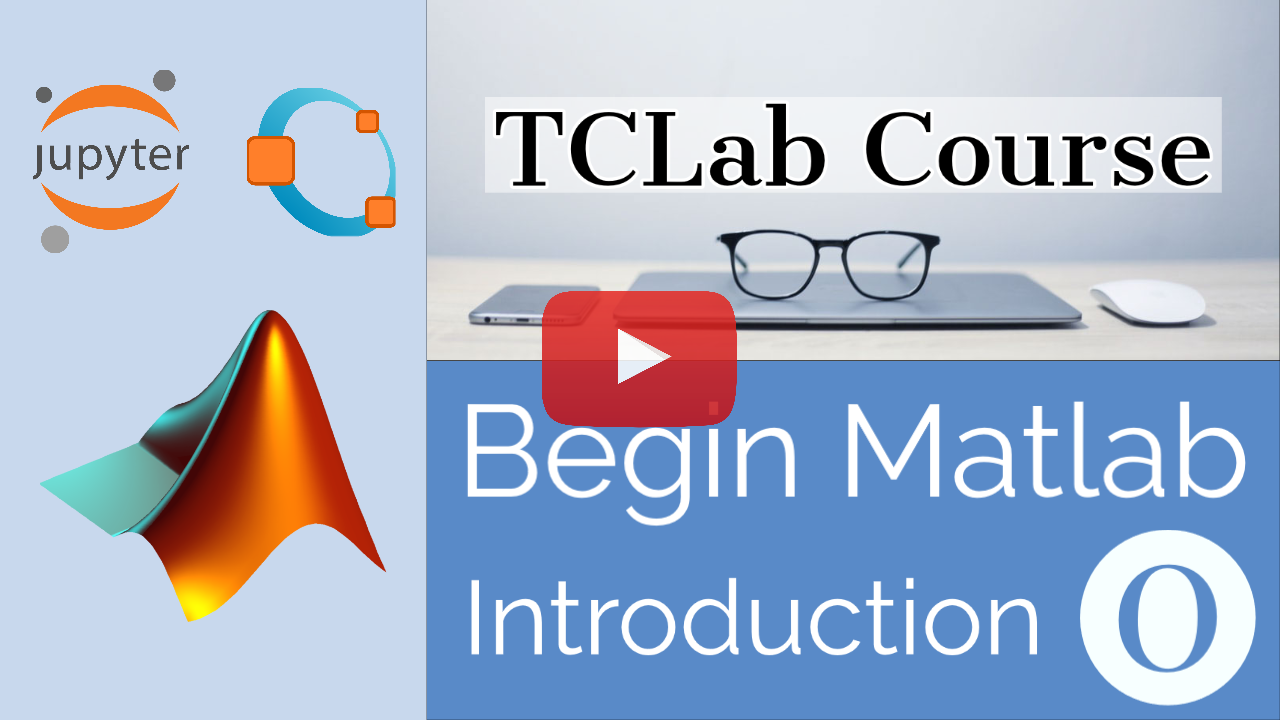

[Click here to watch the video: Course Overview](https://www.youtube.com/watch?v=V8ik7X6I1Sk&list=PLLBUgWXdTBDhJJnJW2q2G7e84MZM6dxRN)

One of the unique things about this course is that you work on basic elements to help you with a temperature control project. You will see your Matlab code have a real effect by adjusting heaters to maintain a target temperature, just like a thermostat in a home or office.

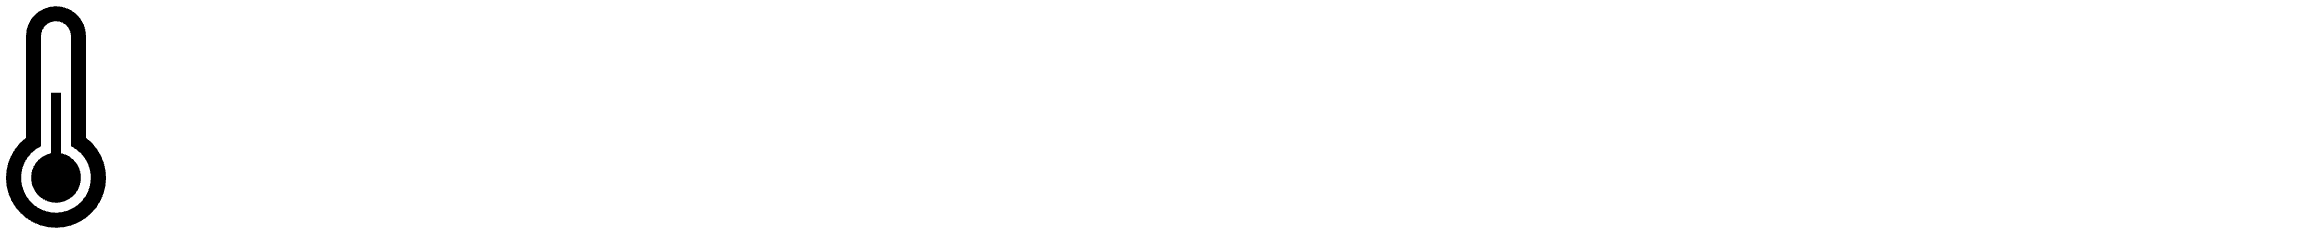

One of the best ways to start or review a programming language is to work on a simple project. These exercises are designed to teach basic Matlab programming skills to help you design a temperature controller.

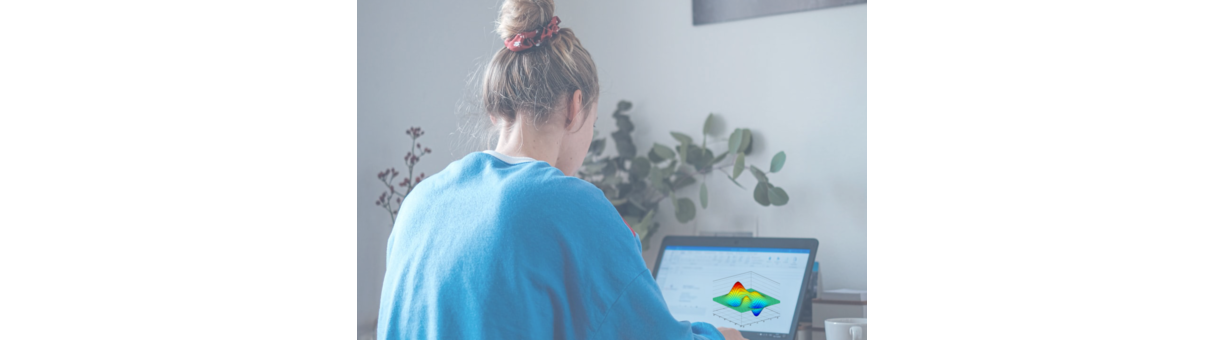

Temperature control is found in many applications such as home or office HVAC, manufacturing processes, transportation, and life sciences. Even our bodies regulate to a specific temperature.

 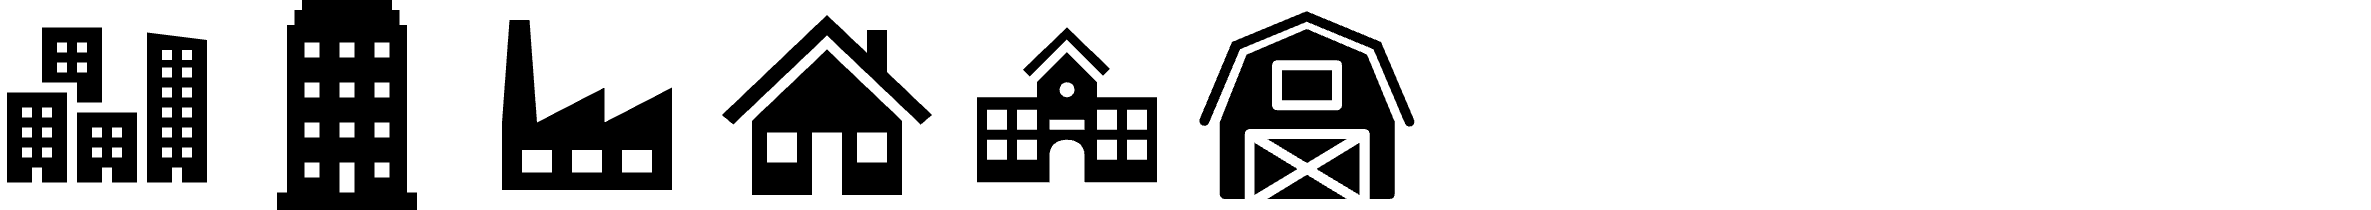

## Step 1: Get a TCLab

This project is to regulate the temperature of the [Temperature Control Lab (TCLab)](https://apmonitor.com/heat.htm). 

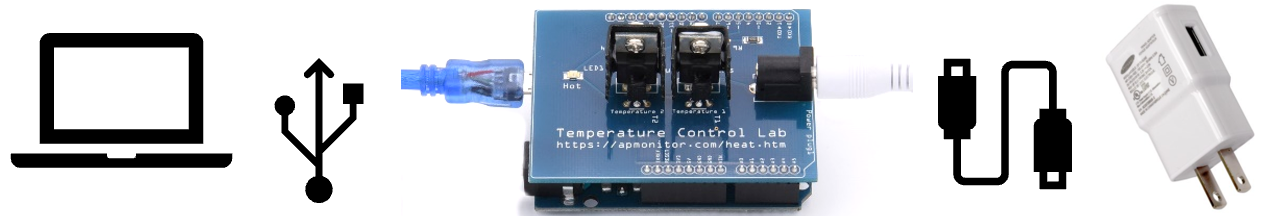

Each TCLab has thermochromic (changes color with temperature) paint that turns from black to purple when the temperature reaches the target temperature of 37°C (99°F). 

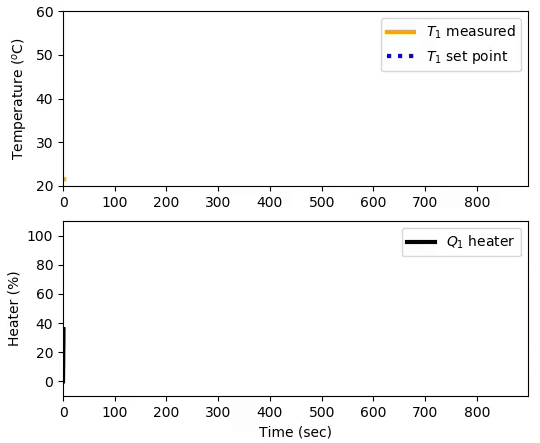

## Step 2: Install Matlab or GNU Octave with Arduino Support

#### 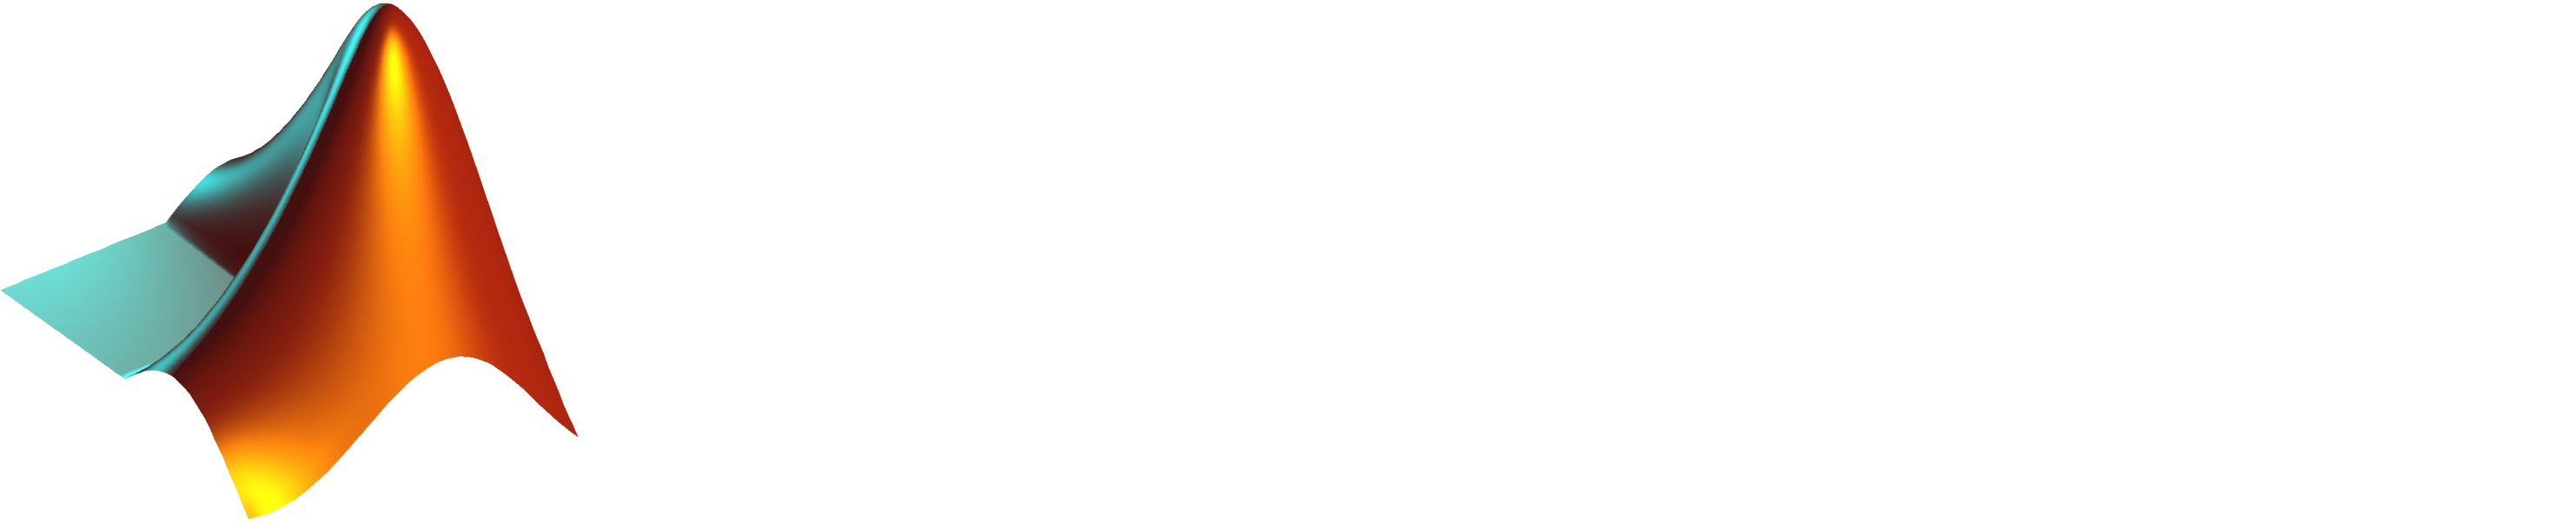

#### Matlab

Install [Matlab](https://www.mathworks.com/products/matlab.html) with the Arduino Support Package for Matlab and Simulink (2 separate Add-ons). The Arduino support package and instructions are available from:

- [MATLAB Arduino support package](https://www.mathworks.com/hardware-support/arduino-matlab.html)

- [Simulink Arduino support package](https://www.mathworks.com/hardware-support/arduino-simulink.html)

After the Matlab Arduino Support package is installed, install the Arduino firmware for Matlab as a one-time setup:

`    arduinosetup`

Once the firmware is loaded, Matlab connects to the Arduino with:

`    a` `=` `arduino`

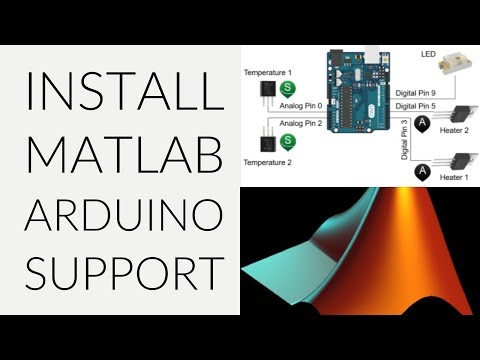

[Click here to watch the video: Install MATLAB Arduino Support](https://www.youtube.com/watch?v=DFvUJh8AYjE)

There are [additional instructions on installing Matlab and managing modules](https://apmonitor.com/che263/index.php/Main/MatlabIntroduction).

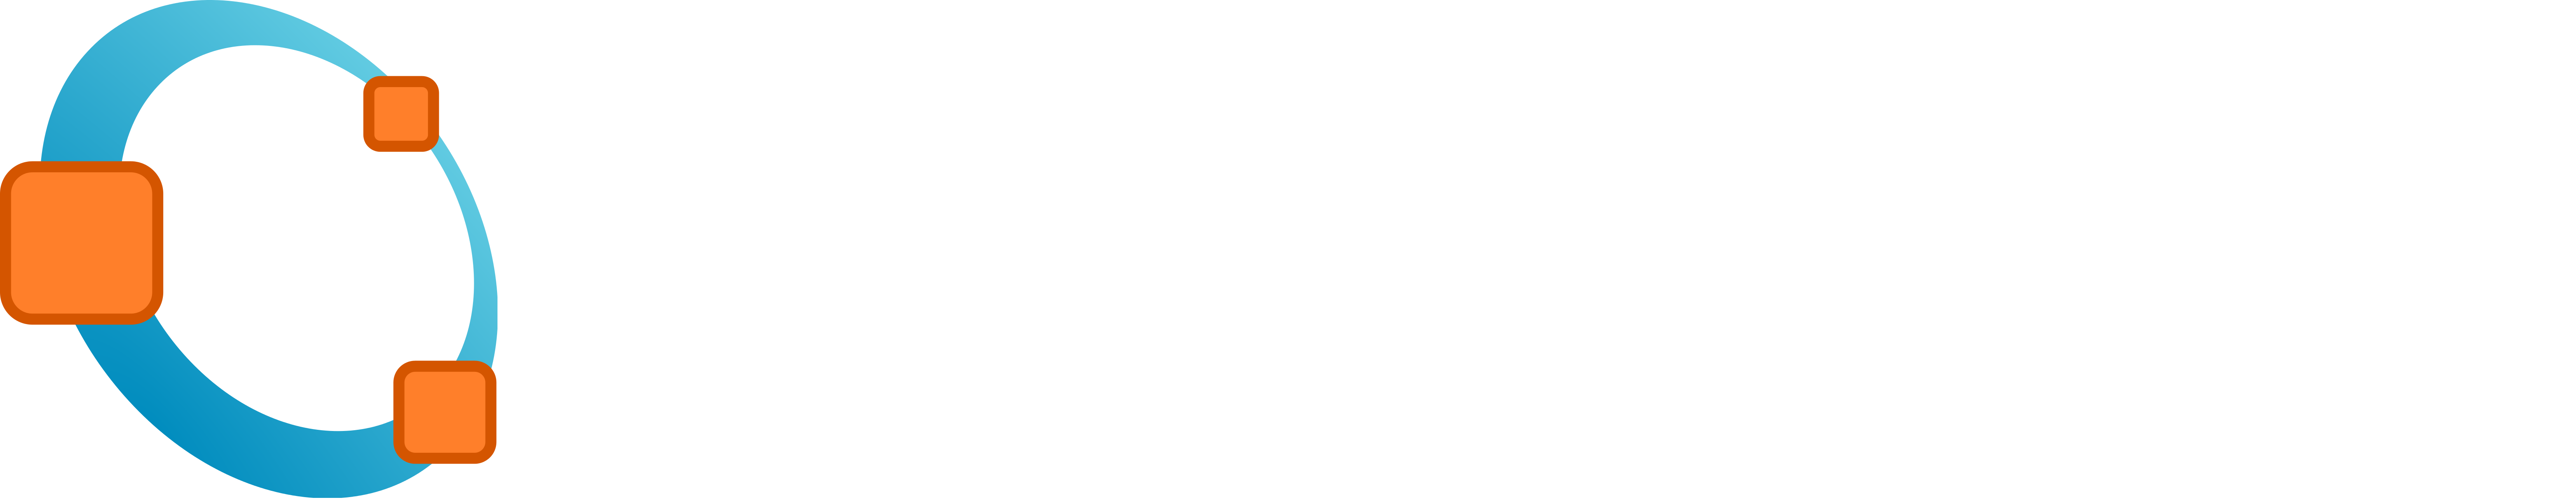

**Octave**

A freely available alternative to Matlab is [GNU Octave](https://www.gnu.org/software/octave/). Octave has very similar syntax to Matlab and can also be used for this course. Install the Arduino support package from the Octave terminal. You can access instructions and the [Arduino package from Octave Forge](https://wiki.octave.org/Arduino_package):

`    pkg` `install` `-``forge` `arduino`

Next, load the Arduino package with:

`    pkg` `load` `arduino`

Finally, install the Arduino firmware for Octave as a one-time setup:

`    arduinosetup`

This requires the Arduino IDE to load the firmware. Once the firmware is loaded, Octave can connect to the Arduino with:

`    a` `=` `arduino`

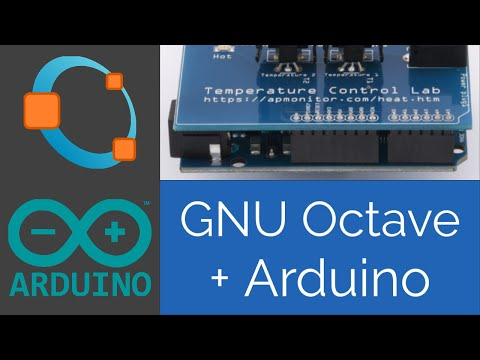

[Click here to watch the video: Install Octave with Arduino Add-On](https://www.youtube.com/watch?v=6UOn1IcNytA)

## Step 3: Install Jupyter Notebook or Jupyter Lab

You can either run the code exercises in the Matlab or Octave or from the Jupyter Notebook. Jupyter is not required for this course but it does make it easier to run code snippets and observe the results. Also the code can be run from a web-browser and fully integrated with the instructions. Jupyter Lab is a newer Integrated Development Environment (IDE) than Jupyter Notebook. It is the next-generation web-based user interface for Project Jupyter. Both Jupyter Lab and Jupyter Notebooks can be used for Matlab or Octave.

This video shows how to install a Project Jupyter IDE (Notebook or Lab) and install the Octave or Matlab kernels for this course. You can [install Jupyter Notebook or Jupyter Lab](https://www.youtube.com/watch?v=eUq-6ZuwC_A) from the command terminal or [install Anaconda](https://www.youtube.com/watch?v=LrMOrMb8-3s) that includes Jupyter Notebook.

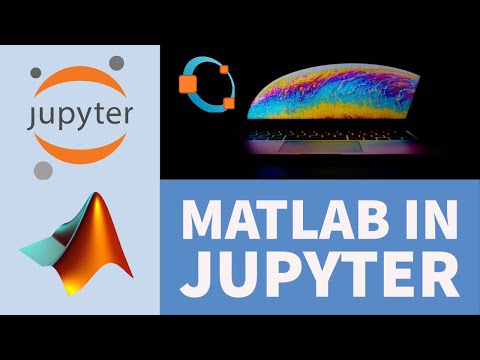

[Click here to watch the video: Matlab in Jupyter Lab Notebook](https://www.youtube.com/watch?v=WufMGW5Bv4g)

### **Option 1: Jupyter Notebook for Matlab**

For Matlab to run in a Jupyter notebook, you need to install the python engine. The MATLAB root for Windows is typically `C:\Program Files\MATLAB\R2020a` or with a another folder such as `R2019a` or `R2018b` that is the version on your computer. The minimum requirement for this course is `R2016a` because earlier versions don't support the Arduino Leonardo connection. Run the following with Administrative privilege with `<matlabroot>` as the Matlab root directory (e.g. `C:\Program Files\MATLAB\R2020a`):

`    cd "<matlabroot>/extern/engines/python"`

`    python setup.py install `

Next, install the Matlab kernel for Jupyter Notebooks or Jupyter Lab

`    pip install matlab_kernel `

### **Option 2: Jupyter Notebook for Octave**

For Octave to run in a Jupyter notebook, you need to install the `octave_kernel`.

`    pip install octave_kernel `

Also, you need to add `octave_cli.exe` to the `PATH` variable in Windows.

### **Test Setup**

You are now all set to go! Run the code below to test that Matlab or Octave runs correctly. To run the cell, select the play button in the toolbar at the top or else type `Ctrl-Enter`. You should see the result of displaying `Test successful` if it is running correctly.

disp('Test successful')

Test successful


### **Switch Kernel Between Octave and Matlab**

Notebook files for this course are provided for MATLAB and Octave but they can easily be switched. The easiest way to switch the kernel is to select **Kernel**...**Change kernel** from the menu.

A Jupyter notebook is a `JSON` text file that can be viewed with any text editor. You can switch between an Octave and Matlab kernel by editing the `.ipynb` file with a text editor or in the Jupyter notebook menu (*Edit*, *Edit Notebook Metadata*) and by replacing **octave / Octave** with **matlab / Matlab**.

#### **Octave in metadata**

`"metadata"``:` `{`  

`    "anaconda-cloud"``:` `{},`  

`    "kernelspec"``:` `{`   

`        "display_name"``:` `"Octave"``,`

`        "language"``:` `"octave"``,`   

`        "name"``:` `"octave"`  

`    }`

#### **Matlab in metadata**

`"metadata"``:` `{`  

`    "kernelspec"``:` `{`   

`    "display_name"``:` `"Matlab"``,`   

`    "language"``:` `"matlab"``,`   

`    "name"``:` `"matlab"`

`    }`